## Demonstration of Chan class family

Load example structure data that were exported from Spike2. It contains multiple channels, each of which is also structure type, in waveform or event format.

close all; clear; clc

pathstr1 = fileparts(which('WaveformChan.m'));

S = load(fullfile(pathstr1,'kjx127a01@0-20_double.mat'));
disp('S =')

S =


disp(S);

        onset: [1x1 struct]
          LTS: [1x1 struct]
        LTSmk: [1x1 struct]
    probeA07e: [1x1 struct]
          EEG: [1x1 struct]



disp('S.EEG =');

S.EEG =


disp(S.EEG);

       title: '…'
     comment: '…'
    interval: 5.8824e-05
       scale: 7.6294e-05
      offset: 0
       units: 'mV'
       start: 0
      length: 340000
      values: [340000x1 double]



disp('S.LTS =');

S.LTS =


disp(S.LTS);

       title: '…'
     comment: '…'
    interval: 5.8824e-05
       start: 0
      length: 340000
      values: [340000x1 double]



## Construction of `Chan` objects by `Chan.constructChan()` method.

`Chan` class is an abstract superclass whose subclasses contains  `WaveformChan` and `MetaEventChan`. `MetaEventChan` is also an abstract class whose subclasses contain `EventChan` and `MarkerChan`.

`.   Chan*`

`.     |`

`.     +-------------------+`

`.     |                   |`

`.   WaveformChan     MetaEventChan*`

`.                       |`

`.               +-------+---------+`

`.               |                 |`

`.           EventChan         MarkerChan`

`.`

`* abstract class ... You cannot construct objects for these classes.`

`                     They only defines format.`

## Construction of an `EventChan` object from structure

`obj = Chan.constructChan(S) `

`%S is Spike2-derived structure of event or waveform data`

The `plot` method is useful for eyeballing the data like Spike2

`chanObject.plot`

finames = fieldnames(S);

S1 = S.(finames{1});

obj1 = Chan.constructChan(S1);
disp(obj1);

  EventChan with properties:

           Data: [340000x1 double]
            ISI: [6x1 double]
    InstantRate: [4x1 double]
     TimeStamps: [7x1 double]
     FiringRate: 0.3500
        NSpikes: 7
          Stats: [1x1 struct]
      ChanTitle: '…'
       DataUnit: ''
          Start: 0
          SRate: 17000
         Header: [1x1 struct]
           Path: ''
     ChanNumber: 0
         Length: 340000
      SInterval: 5.8824e-05
        MaxTime: 19.9999
       TimeUnit: '…'



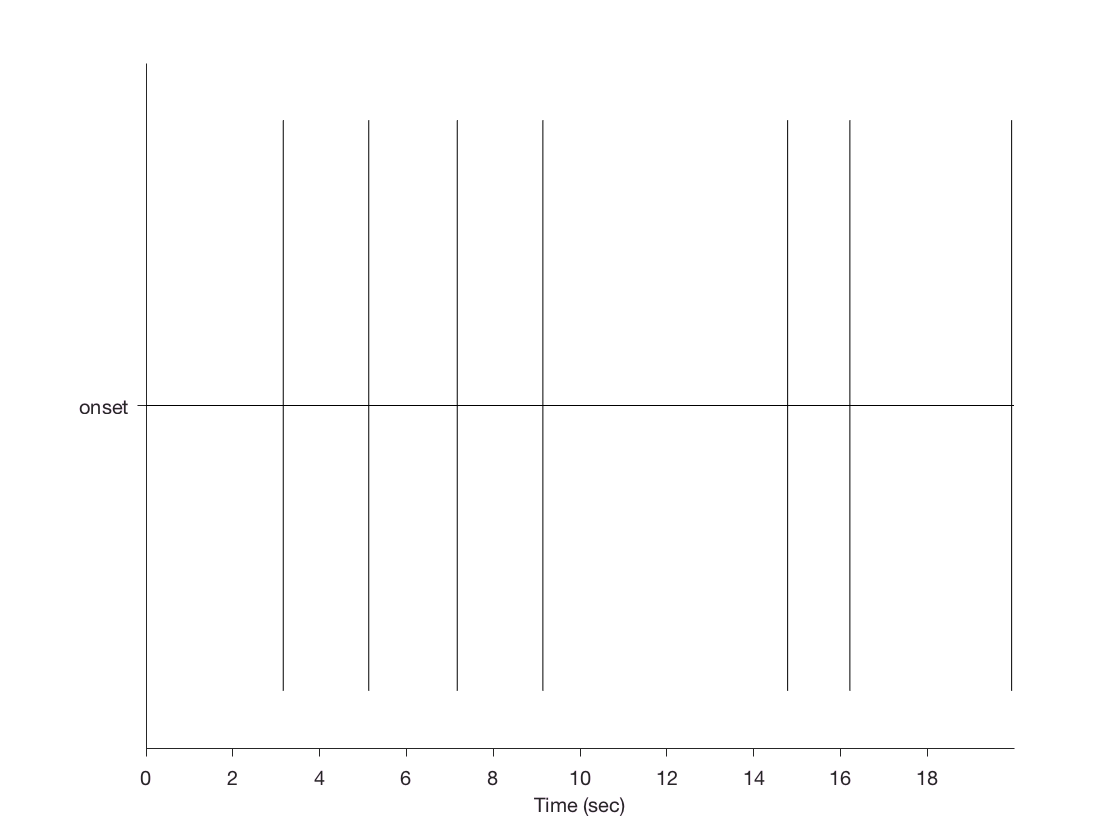

obj1.plot;

## Construction of a `WaveformChan` object from structure

S2 = S.(finames{5});

obj2 = Chan.constructChan(S2);
disp(obj2);

  WaveformChan with properties:

          Data: [340000x1 double]
         Scale: 7.6294e-05
        Offset: 0
     ChanTitle: '…'
      DataUnit: 'mV'
         Start: 0
         SRate: 17000
        Header: [1x1 struct]
          Path: ''
    ChanNumber: 0
        Length: 340000
     SInterval: 5.8824e-05
       MaxTime: 19.9999
      TimeUnit: '…'



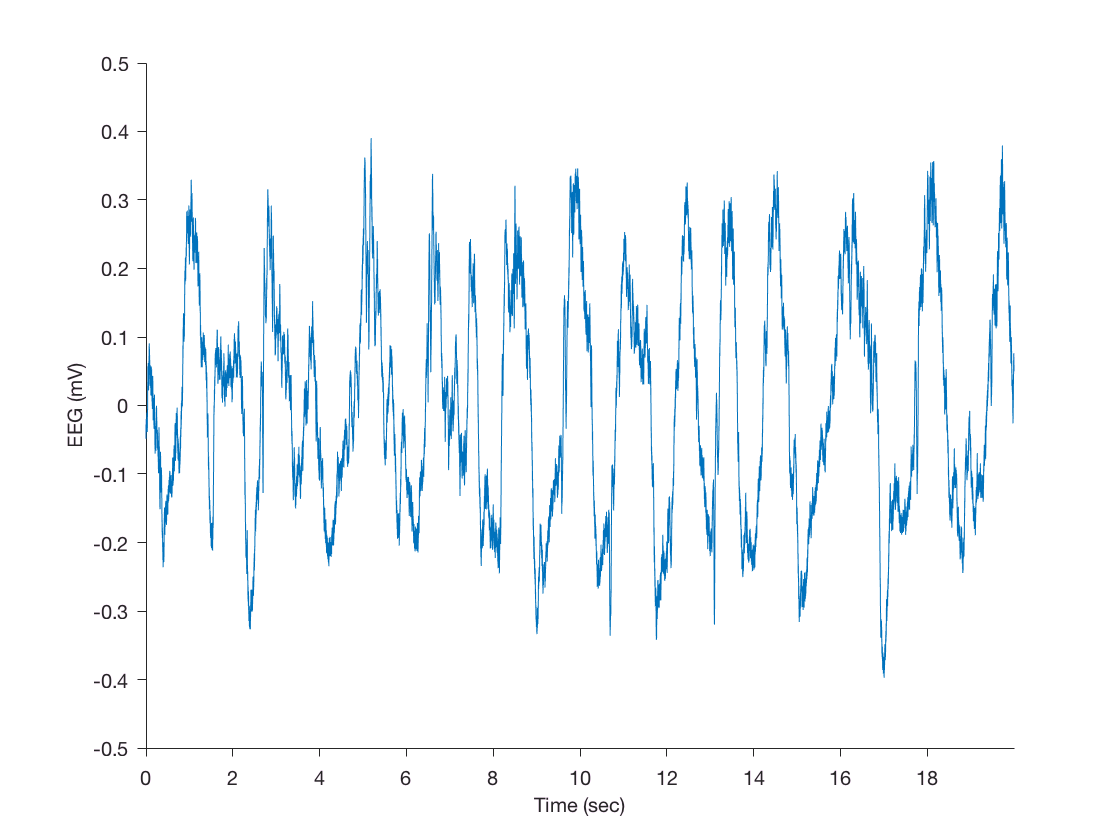

obj2.plot;

## Alternative: `EventChan` and `WaveformChan` constructor

If you know the data type in advance, you can directly use `EventChan` constructor instead.

`obj = EventChan(S) % S is a structure containing event data`

obj1 = EventChan(S1);
fprintf('obj1 is %s\n', class(obj1))

obj1 is EventChan


If you know the data type in advance, you can directly use `WaveformChan` constructor instead.

`obj = WaveformChan(S) % S is a structure containing waveform data`

obj2 = WaveformChan(S2);
fprintf('obj2 is %s\n', class(obj2))

obj2 is WaveformChan


However, if you choose wrong data type as input argument, it will result in an error.

`obj2 = WaveformChan(S1); % where S1 is event type`

`   Error using WaveformChan (line 129)`

`   struct doesn't seem Spike2 waveform format`

`   Error in Chan_demo (line 74)`

`   obj2 = WaveformChan(S1);`

## Construction of multiple `EventChan` and `WaveformChan` objects at the same time

`[obj1, obj2] = Chan.constructChan(S1, S2)`

`% where S1, S2 and so on are Spike2-derived structure of event or`

`waveform data type.`

clear obj1 obj2

finames = fieldnames(S);

[obj1, obj2, obj3, obj4, obj5] = ...
    Chan.constructChan(S.(finames{1}), S.(finames{2}), S.(finames{3}), S.(finames{4}), S.(finames{5}));
fprintf('obj1 is %s\n', class(obj1))

obj1 is EventChan


fprintf('obj2 is %s\n', class(obj2))

obj2 is EventChan


fprintf('obj3 is %s\n', class(obj3))

obj3 is EventChan


fprintf('obj4 is %s\n', class(obj4))

obj4 is EventChan


fprintf('obj5 is %s\n', class(obj5))

obj5 is WaveformChan


## Construction of `MarkerChan` object

pathstr2 = fileparts(which('MarkerChan.m'));

S = load(fullfile(pathstr2,'markerchan_demodata.mat'));
finames = fieldnames(S);

MarkerChan object requires another **reference structure** that is either in `event` or `waveform` format in order to determine the `MaxTime` property.

Note that attempts to construct a `MarkerChan` object with only one structure that contains `marker` or `textmark` data will result in an error.

`Chan.constructChan(S.(finames{1}))`

`   Error using Chan.constructChan (line 396)`

`   Input includes marker data type but reference ref was not provided.`

`MarkerChan(S.(finames{1}))`

`   Error using MarkerChan (line 228)`

`   Not enough input arguments.`

With reference structure, it will succeed.

`obj = MarkerChan(S1, S0)`

`% where S1 is marker or textmark data type, whereas S0 is event or`

`waveform data type. Both S1 and S0 are derived from the same Spike2`

`file.`

obj7 = MarkerChan(S.(finames{1}),  S.(finames{2}));
disp(obj7)

  MarkerChan with properties:

                Data: [1700000x1 double]
    IsMarkerFilterOn: 0
        MarkerFilter: [256x4 dataset]
          MarkerName: {256x4 cell}
            TextMark: {98x1 cell}
         MarkerCodes: [98x4 uint8]
                 ISI: [97x1 double]
         InstantRate: [95x1 double]
          TimeStamps: [98x1 double]
          FiringRate: 0.9800
             NSpikes: 98
               Stats: [1x1 struct]
           ChanTitle: '…'
            DataUnit: ''
               Start: 0
               SRate: 17000
              Header: [1x1 struct]
                Path: ''
          ChanNumber: 0
              Length: 1700000
           SInterval: 5.8824e-05
             MaxTime: 99.9999
            TimeUnit: '…'



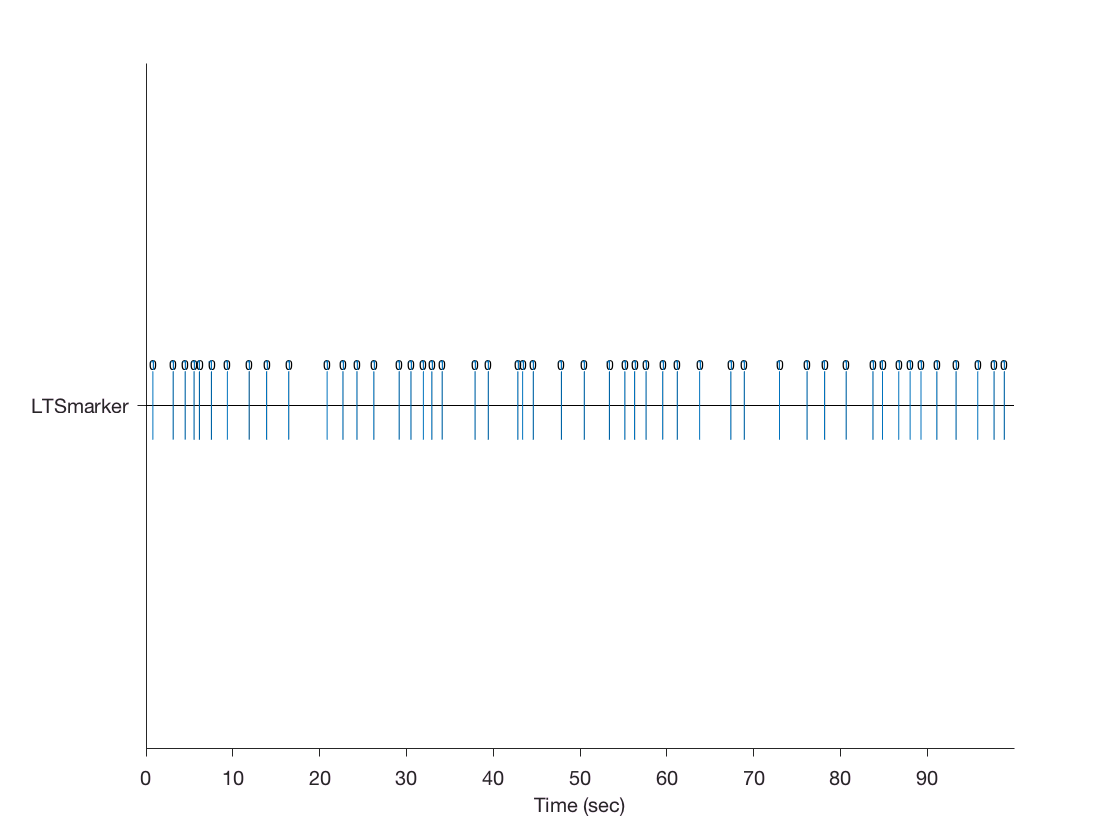

obj7.plot;

An alternative way to construct a `MarkerChan` object.

`[obj1, obj2] = Chan.constructChan(S1, S2, 'ref', S0)`

where `S1`, `S2`, and so on and `S0` are all derived from the same Spike2 file. While `S1`, `S2`, and so on can be of any data type, including `marker` or `textmark`, the reference `S0` must be either `waveform` or `event` data type.

[obj6, obj7] =  Chan.constructChan(S.(finames{1}), S.(finames{3}),'ref',  S.(finames{2}));
fprintf('obj6 is %s\n', class(obj6))

obj6 is MarkerChan


fprintf('obj7 is %s\n', class(obj7))

obj7 is MarkerChan
